% Clearing
clc;
clear;

% Getting data
filename = "./Step2021-6x4x3.xlsx";
errikos_data = xlsread(filename, 1, "A2:H568");

time = errikos_data(:,1);
esc_signal = errikos_data(:,2);
throttle = errikos_data(:,3);
thrust_kgf = errikos_data(:,4);
voltage_v = errikos_data(:,5);
current_a = errikos_data(:,6);
electricalPow_w = errikos_data(:,7);

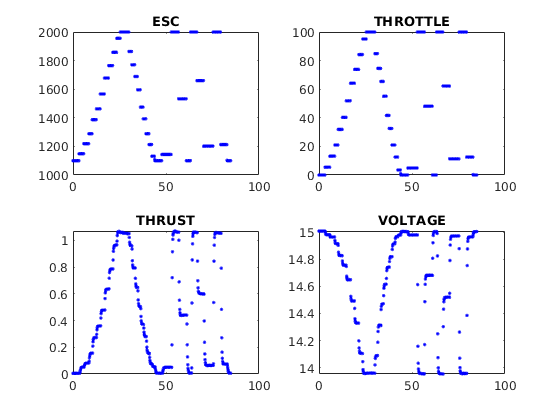

% Overview
figure()
subplot(2,2,1)
plot(time, esc_signal,"b.")
title("ESC")

subplot(2,2,2)
plot(time, throttle,"b.")
title("THROTTLE")

subplot(2,2,3)
plot(time, thrust_kgf, "b.")
title("THRUST")

subplot(2,2,4)
plot(time, voltage_v, "b.")
title("VOLTAGE")

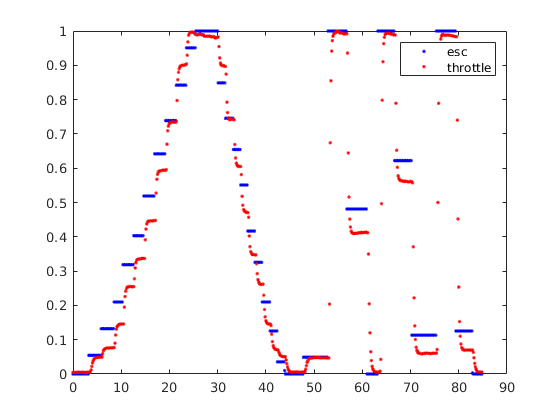

% Thurst and esc signal
normed_esc = esc_signal - 1100;         % 1100 is base signal
normed_esc = normed_esc / max(normed_esc);
normed_thrust = thrust_kgf / max(thrust_kgf);
%normed_thrust = throttle / max(throttle);

figure()
plot(time, normed_esc,".b")
hold on
plot(time, normed_thrust,".r")
hold off
legend("esc", "throttle")

% 1st step input and response
start_i = 10;
end_i = 41;
time_start = time(min(find(normed_esc > 0))) % time of first non-zero signal

time_start = 3.3017

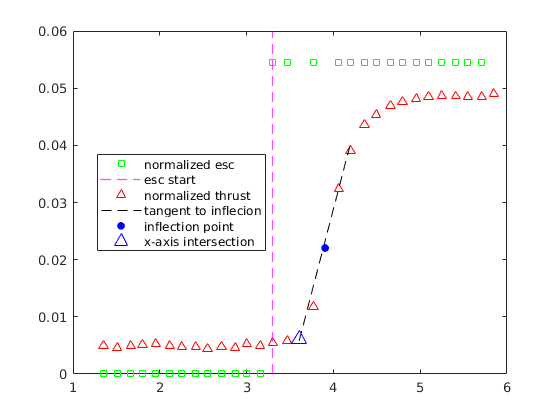

%f = fit(time(25:30), normed_esc(25:30), "poly2");

to_plot_time = time(start_i:end_i);
to_plot_ESC = normed_esc(start_i:end_i);
to_plot_thrust = normed_thrust(start_i:end_i);

to_plot_time(26-start_i) = [];
to_plot_ESC(26-start_i) = [];
to_plot_thrust(26-start_i) = [];
to_plot_time(27-start_i) = [];
to_plot_ESC(27-start_i) = [];
to_plot_thrust(27-start_i) = [];

figure()
plot(to_plot_time, to_plot_ESC, "sg")
hold on
xline(time_start, "--m", "LineWidt", 1);
plot(to_plot_time, to_plot_thrust, "^r")

tang_grad = (normed_thrust(29) - normed_thrust(27)) / (time(29) - time(27));
tang_intersect = normed_thrust(28) - tang_grad * time(28);
range = time(25):0.01:time(29);
pts = tang_grad * range + tang_intersect;

plot(range, pts, "--k");                                  % tangent
plot(time(27), normed_thrust(27), ".b", "MarkerSize", 20) % inflection point
plot(time(25), normed_thrust(25), "^b", "MarkerSize", 10) % intersection point of tanget

xlim([1,6]);
hold off
legend("normalized esc", "esc start", "normalized thrust", "tangent to inflecion", "inflection point", "x-axis intersection", "Location","best")
ylim([0, 0.06])

time_25 = time(25);                    % x of intersection
%time_25 = 3.68484;       ??? why this?

delta = time_25 - time_start           % from paper?

delta = 0.3031